# **Script d'analyse EMG pour comparer sujet par sujet les populations**

% 1. Charge les données des 3 fichiers .mat (asymptomatique, pre, post)
% 2. Extrait les données EMG pour chaque sujet
% 3. Pour chaque mouvement fonctionnel (1 à 4):
%    a. Calcule la moyenne des 10 valeurs les plus hautes
%    b. Fait la moyenne de ces valeurs sur les 4 mouvements
% 4. Combine les données des côtés droit et gauche
% 5. Effectue des comparaisons statistiques: 
%    - asympt vs post (indépendant)
%    - asympt vs pre (indépendant)
%    - pre vs post (apparié)
% 6. Produit des visualisations (boxplots) avec des p-values clairement visibles

%% 1. Définition des paramètres
clear all;
close all;
clc;

% Chemins des fichiers à charger
file_asympt = 'combined_functional_data_ASYMPTO'; 
file_pre = 'combined_functional_data_PREOP';              
file_post = 'combined_functional_data_POSTOP';

% Nombre de valeurs maximales à utiliser pour la moyenne
n_max_values = 10;

% Liste des muscles à analyser
muscles = {'Anterior Deltoid', 'Middle Deltoid', 'Posterior Deltoid', ...
           'Middle Trapezius', 'Upper Trapezius', 'Serratus Anterior'};
nb_muscles = length(muscles);

%% 2. Chargement des données
fprintf('Chargement des données...\n');

Chargement des données...



% Chargement des données asymptomatiques
data_asympt = load(file_asympt);

% Chargement des données pre-opératoires
data_pre = load(file_pre);

% Chargement des données post-opératoires
data_post = load(file_post);

%% 3. Extraction et traitement des données EMG

% Fonction pour traiter les données d'un groupe et combiner les côtés droit et gauche
function results = process_group_data(data, n_max_values)
    results = struct();
    
    % Extraction des informations de base
    functional_labels = data.individual_data.functional_labels;
    nb_functionals = length(functional_labels);
    
    % Pour les sujets côté droit
    subjects_R = data.individual_data.subject_ids_R;
    nb_subjects_R = length(subjects_R);
    
    % Pour les sujets côté gauche
    subjects_L = data.individual_data.subject_ids_L;
    nb_subjects_L = length(subjects_L);
    
    % Muscles
    muscles_R = data.individual_data.muscles_R;
    muscles_L = data.individual_data.muscles_L;
    nb_muscles_R = length(muscles_R);
    nb_muscles_L = length(muscles_L);
    
    % Initialisation des résultats pour stocker les moyennes des n valeurs max
    results.subjects_R = subjects_R;
    results.subjects_L = subjects_L;
    results.muscles_R = muscles_R;
    results.muscles_L = muscles_L;
    
    % Matrices pour stocker les résultats (moyenne des n valeurs max)
    results.max_values_R = zeros(nb_subjects_R, nb_muscles_R);
    results.max_values_L = zeros(nb_subjects_L, nb_muscles_L);

% ---- POUR LE CÔTÉ DROIT ----
% Traitement des données côté droit
for subj_idx = 1:nb_subjects_R
    % Pour chaque muscle
    for muscle_idx = 1:nb_muscles_R
        % Initialiser un vecteur pour stocker la moyenne des 4 mouvements pour ce muscle
        subject_mean_data = zeros(1, 0);
        valid_func_count = 0;
        
        % Combiner les données des 4 mouvements fonctionnels
        for func_idx = 1:min(4, nb_functionals)
            if ~isempty(data.individual_data.subject_data_R{subj_idx, func_idx})
                % Extraire les données du muscle pour ce mouvement
                muscle_data = data.individual_data.subject_data_R{subj_idx, func_idx}(:, muscle_idx);
                
                % Si c'est le premier mouvement valide, initialiser subject_mean_data
                if valid_func_count == 0
                    subject_mean_data = zeros(size(muscle_data));
                end
                
                % Ajouter à la moyenne
                subject_mean_data = subject_mean_data + muscle_data;
                valid_func_count = valid_func_count + 1;
            end
        end
        
        % Calculer la moyenne des mouvements (si au moins un mouvement est valide)
        if valid_func_count > 0
            subject_mean_data = subject_mean_data / valid_func_count;
            
            % Trouver la valeur maximale de cette moyenne
            results.max_values_R(subj_idx, muscle_idx) = max(subject_mean_data);
        end
    end
end

% ---- POUR LE CÔTÉ GAUCHE ----
% Traitement des données côté gauche
for subj_idx = 1:nb_subjects_L
    % Pour chaque muscle
    for muscle_idx = 1:nb_muscles_L
        % Initialiser un vecteur pour stocker la moyenne des 4 mouvements pour ce muscle
        subject_mean_data = zeros(1, 0);
        valid_func_count = 0;
        
        % Combiner les données des 4 mouvements fonctionnels
        for func_idx = 1:min(4, nb_functionals)
            if ~isempty(data.individual_data.subject_data_L{subj_idx, func_idx})
                % Extraire les données du muscle pour ce mouvement
                muscle_data = data.individual_data.subject_data_L{subj_idx, func_idx}(:, muscle_idx);
                
                % Si c'est le premier mouvement valide, initialiser subject_mean_data
                if valid_func_count == 0
                    subject_mean_data = zeros(size(muscle_data));
                end
                
                % Ajouter à la moyenne
                subject_mean_data = subject_mean_data + muscle_data;
                valid_func_count = valid_func_count + 1;
            end
        end
        
        % Calculer la moyenne des mouvements (si au moins un mouvement est valide)
        if valid_func_count > 0
            subject_mean_data = subject_mean_data / valid_func_count;
            
            % Trouver la valeur maximale de cette moyenne
            results.max_values_L(subj_idx, muscle_idx) = max(subject_mean_data);
        end
    end
end
    
    % Combiner les données des côtés droit et gauche
    % Vérifier le format des identifiants de sujets pour s'assurer qu'ils sont compatibles
    if iscell(subjects_R) && iscell(subjects_L)
        % Si ce sont des cellules, on peut les concaténer directement
        results.all_subjects = [subjects_R; subjects_L];
    elseif isnumeric(subjects_R) && isnumeric(subjects_L)
        % Si ce sont des nombres, il faut s'assurer qu'ils ont le même nombre de colonnes
        if size(subjects_R, 2) == size(subjects_L, 2)
            results.all_subjects = [subjects_R; subjects_L];
        else
            % Créer un identifiant unique pour chaque sujet
            results.all_subjects = [(1:nb_subjects_R)'; (nb_subjects_R+1:nb_subjects_R+nb_subjects_L)'];
            fprintf('Note: Identifiants de sujets incompatibles, création d''identifiants numériques uniques\n');
        end
    else
        % Types différents, on crée des identifiants numériques uniques
        results.all_subjects = [(1:nb_subjects_R)'; (nb_subjects_R+1:nb_subjects_R+nb_subjects_L)'];
        fprintf('Note: Types d''identifiants incompatibles, création d''identifiants numériques uniques\n');
    end
    
    % Vérifier que les deux matrices de valeurs ont le même nombre de colonnes
    if size(results.max_values_R, 2) == size(results.max_values_L, 2)
        results.all_max_values = [results.max_values_R; results.max_values_L];
    else
        % Si nombre de muscles différent, on utilise l'intersection
        common_cols = min(size(results.max_values_R, 2), size(results.max_values_L, 2));
        results.all_max_values = [results.max_values_R(:, 1:common_cols); results.max_values_L(:, 1:common_cols)];
        fprintf('Note: Nombre de muscles différent entre côté droit et gauche, utilisation des %d premiers muscles\n', common_cols);
    end
end

% Traitement des trois groupes de données
fprintf('Traitement des données asymptomatiques...\n');

Traitement des données asymptomatiques...


results_asympt = process_group_data(data_asympt, n_max_values);

Note: Identifiants de sujets incompatibles, création d'identifiants numériques uniques



fprintf('Traitement des données pre-opératoires...\n');

Traitement des données pre-opératoires...


results_pre = process_group_data(data_pre, n_max_values);

fprintf('Traitement des données post-opératoires...\n');

Traitement des données post-opératoires...


=== Analyse statistique: Control vs Post (indépendant) ===

--- Anterior Deltoid ---


Test utilisé: Test de Mann-Whitney (normalité: p = 0.0010)
Control: M = 39.69, ET = 16.24; Post: M = 51.07, ET = 21.53
Résultat: Z = -1.66, p = 0.0962 (non significatif)
Interprétation: Pas de différence significative entre Control et Post
Taille d'effet: d de Cohen = 0.60 (effet moyen)

--- Middle Deltoid ---


Test utilisé: Test t indépendant (normalité: p = 0.4260)
Control: M = 30.59, ET = 13.82; Post: M = 42.43, ET = 10.25
Résultat: t(38) = -3.08, p = 0.0039 (significatif)
Interprétation: augmentation significative entre Control et Post
Taille d'effet: d de Cohen = 0.97 (effet fort)

--- Posterior Deltoid ---
Test utilisé: Test t indépendant (normalité: p = 0.0791)
Control: M = 63.03, ET = 40.06; Post: M = 72.48, ET = 25.89
Résultat: t(38) = -0.89, p = 0.3809 (non significatif)
Interprétation: Pas de différence significative entre Control et Post
Taille d'effet: d de Cohen = 0.28 (effet faible)

--- Middle Trapezius ---


Test utilisé: Test t indépendant (normalité: p = 0.2074)
Control: M = 27.72, ET = 15.64; Post: M = 29.90, ET = 17.13
Résultat: t(38) = -0.42, p = 0.6772 (non significatif)
Interprétation: Pas de différence significative entre Control et Post
Taille d'effet: d de Cohen = 0.13 (effet négligeable)

--- Upper Trapezius ---


Test utilisé: Test t indépendant (normalité: p = 0.5000)
Control: M = 35.87, ET = 14.22; Post: M = 46.96, ET = 11.65
Résultat: t(38) = -2.70, p = 0.0104 (significatif)
Interprétation: augmentation significative entre Control et Post
Taille d'effet: d de Cohen = 0.85 (effet fort)

--- Serratus Anterior ---


Test utilisé: Test t indépendant (normalité: p = 0.3946)
Control: M = 33.55, ET = 14.36; Post: M = 52.12, ET = 21.17
Résultat: t(38) = -3.25, p = 0.0024 (significatif)
Interprétation: augmentation significative entre Control et Post
Taille d'effet: d de Cohen = 1.03 (effet fort)



=== Tableau récapitulatif: Control vs Post ===
           Muscle            Group1_Mean    Group1_SD    Group2_Mean    Group2_SD     P_Value     Effect_Size
    _____________________    ___________    _________    ___________    _________    _________    ___________

    {'Anterior Deltoid' }      39.694        16.238        51.071        21.533       0.096196      0.59654  
    {'Middle Deltoid'   }      30.591        13.822        42.426        10.249      0.0038792      0.97265  
    {'Posterior Deltoid'}      63.028        40.055        72.484        25.894        0.38088      0.28036  
    {'Middle Trapezius' }      27.721        15.645        29.897        17.127        0.67724      0.13265  
    {'Upper Trapezius'  }      35.871        14.223   

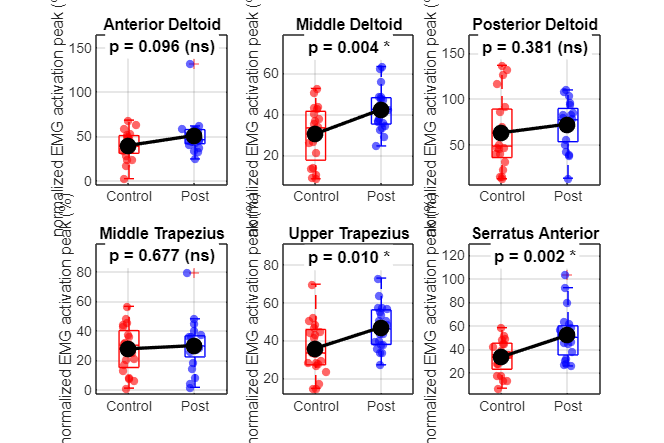

results_post = process_group_data(data_post, n_max_values);

%% 4. Préparation des données pour l'analyse statistique

% Fonction pour préparer les données pour l'analyse (combinées)
function data_combined = prepare_data_for_analysis(results)
    data_combined = results.all_max_values;
end

% Préparation des données combinées
data_asympt_combined = prepare_data_for_analysis(results_asympt);
data_pre_combined = prepare_data_for_analysis(results_pre);
data_post_combined = prepare_data_for_analysis(results_post);

%% 5. Analyse statistique

% Pour identifier les sujets communs entre pré et post (pour les tests appariés)
common_subjects_pre_post = intersect(results_pre.all_subjects, results_post.all_subjects);

% Créer des indices pour mapper les sujets communs
[~, idx_pre] = ismember(common_subjects_pre_post, results_pre.all_subjects);
[~, idx_post] = ismember(common_subjects_pre_post, results_post.all_subjects);

% Fonction pour effectuer les tests statistiques entre deux groupes
function perform_statistical_analysis(data1, data2, group1_name, group2_name, is_paired, muscles)
    nb_muscles = size(data1, 2);
    
    fprintf('=== Analyse statistique: %s vs %s (%s) ===\n\n', ...
        group1_name, group2_name, conditional(is_paired, 'apparié', 'indépendant'));
    
    for muscle_idx = 1:nb_muscles
        fprintf('--- %s ---\n', muscles{muscle_idx});
        
        % Extraction des données pour le muscle actuel
        muscle_data1 = data1(:, muscle_idx);
        muscle_data2 = data2(:, muscle_idx);
        
        % Éliminer les NaN
        valid_idx1 = ~isnan(muscle_data1);
        valid_idx2 = ~isnan(muscle_data2);
        
        if is_paired
            % Pour les tests appariés, on ne garde que les indices valides dans les deux groupes
            valid_idx = valid_idx1 & valid_idx2;
            muscle_data1 = muscle_data1(valid_idx);
            muscle_data2 = muscle_data2(valid_idx);
        else
            % Pour les tests indépendants, on traite chaque groupe séparément
            muscle_data1 = muscle_data1(valid_idx1);
            muscle_data2 = muscle_data2(valid_idx2);
        end
        
        % Calcul des deltas (pour les tests appariés)
        if is_paired
            delta_data = muscle_data2 - muscle_data1;
        end
        
        % Test de normalité
        if is_paired
            [H_sw, p_sw] = swtest(delta_data, 0.05);
        else
            % Pour les tests indépendants, on vérifie la normalité de chaque groupe
            [H_sw1, p_sw1] = swtest(muscle_data1, 0.05);
            [H_sw2, p_sw2] = swtest(muscle_data2, 0.05);
            H_sw = H_sw1 | H_sw2; % Si l'un des deux rejette la normalité
            p_sw = min(p_sw1, p_sw2); % Le p le plus faible
        end
        
        normalite = ~H_sw;
        
        % Choix du test statistique approprié
        if is_paired
            if normalite
                % Test t apparié si les différences suivent une loi normale
                [h, p_value, ci, stats] = ttest(muscle_data1, muscle_data2);
                test_type = 'Test t apparié';
                t_val = stats.tstat;
                df = stats.df;
                test_stat = sprintf('t(%d) = %.2f', df, t_val);
            else
                % Test de Wilcoxon pour échantillons appariés
                [p_value, h, stats] = signrank(muscle_data1, muscle_data2);
                test_type = 'Test de Wilcoxon (échantillons appariés)';
                % Corriger le problème de zval manquant
                if isfield(stats, 'zval')
                    test_stat = sprintf('Z = %.2f', stats.zval);
                else
                    test_stat = 'statistique non disponible';
                end
            end
        else
            if normalite
                % Test t indépendant
                [h, p_value, ci, stats] = ttest2(muscle_data1, muscle_data2);
                test_type = 'Test t indépendant';
                t_val = stats.tstat;
                df = stats.df;
                test_stat = sprintf('t(%d) = %.2f', df, t_val);
            else
                % Test de Mann-Whitney
                [p_value, h, stats] = ranksum(muscle_data1, muscle_data2);
                test_type = 'Test de Mann-Whitney';
                % Corriger le problème de zval manquant
                if isfield(stats, 'zval')
                    test_stat = sprintf('Z = %.2f', stats.zval);
                else
                    test_stat = 'statistique non disponible';
                end
            end
        end
        
        % Calcul de la taille d'effet
        if is_paired
            cohen_d = mean(delta_data) / std(delta_data);
        else
            pooled_std = sqrt(((length(muscle_data1)-1)*var(muscle_data1) + ...
                              (length(muscle_data2)-1)*var(muscle_data2)) / ...
                              (length(muscle_data1) + length(muscle_data2) - 2));
            cohen_d = (mean(muscle_data2) - mean(muscle_data1)) / pooled_std;
        end
        
        % Rapport des résultats
        fprintf('Test utilisé: %s (normalité: p = %.4f)\n', test_type, p_sw);
        fprintf('%s: M = %.2f, ET = %.2f; %s: M = %.2f, ET = %.2f\n', ...
            group1_name, mean(muscle_data1), std(muscle_data1), ...
            group2_name, mean(muscle_data2), std(muscle_data2));
        fprintf('Résultat: %s, p = %.4f', test_stat, p_value);
        
        % Interprétation
        if p_value < 0.05
            fprintf(' (significatif)\n');
            if is_paired
                direction = conditional(mean(delta_data) > 0, 'augmentation', 'diminution');
            else
                direction = conditional(mean(muscle_data2) > mean(muscle_data1), 'augmentation', 'diminution');
            end
            fprintf('Interprétation: %s significative entre %s et %s\n', ...
                direction, group1_name, group2_name);
        else
            fprintf(' (non significatif)\n');
            fprintf('Interprétation: Pas de différence significative entre %s et %s\n', ...
                group1_name, group2_name);
        end
        
        fprintf('Taille d''effet: d de Cohen = %.2f (%s)\n\n', ...
            cohen_d, interpretCohenD(cohen_d));
    end
    
    % Création d'un tableau récapitulatif
    results_table = table;
    results_table.Muscle = muscles';
    results_table.Group1_Mean = zeros(nb_muscles, 1);
    results_table.Group1_SD = zeros(nb_muscles, 1);
    results_table.Group2_Mean = zeros(nb_muscles, 1);
    results_table.Group2_SD = zeros(nb_muscles, 1);
    if is_paired
        results_table.Delta_Mean = zeros(nb_muscles, 1);
        results_table.Delta_SD = zeros(nb_muscles, 1);
    end
    results_table.P_Value = zeros(nb_muscles, 1);
    results_table.Effect_Size = zeros(nb_muscles, 1);
    
    for muscle_idx = 1:nb_muscles
        muscle_data1 = data1(:, muscle_idx);
        muscle_data2 = data2(:, muscle_idx);
        
        % Éliminer les NaN
        valid_idx1 = ~isnan(muscle_data1);
        valid_idx2 = ~isnan(muscle_data2);
        
        if is_paired
            valid_idx = valid_idx1 & valid_idx2;
            muscle_data1 = muscle_data1(valid_idx);
            muscle_data2 = muscle_data2(valid_idx);
            delta_data = muscle_data2 - muscle_data1;
            
            results_table.Group1_Mean(muscle_idx) = mean(muscle_data1);
            results_table.Group1_SD(muscle_idx) = std(muscle_data1);
            results_table.Group2_Mean(muscle_idx) = mean(muscle_data2);
            results_table.Group2_SD(muscle_idx) = std(muscle_data2);
            results_table.Delta_Mean(muscle_idx) = mean(delta_data);
            results_table.Delta_SD(muscle_idx) = std(delta_data);
            
            if swtest(delta_data, 0.05) == 0 % Normalité
                [~, p] = ttest(muscle_data1, muscle_data2);
            else
                [p, ~] = signrank(muscle_data1, muscle_data2);
            end
            
            results_table.P_Value(muscle_idx) = p;
            results_table.Effect_Size(muscle_idx) = mean(delta_data) / std(delta_data);
        else
            muscle_data1 = muscle_data1(valid_idx1);
            muscle_data2 = muscle_data2(valid_idx2);
            
            results_table.Group1_Mean(muscle_idx) = mean(muscle_data1);
            results_table.Group1_SD(muscle_idx) = std(muscle_data1);
            results_table.Group2_Mean(muscle_idx) = mean(muscle_data2);
            results_table.Group2_SD(muscle_idx) = std(muscle_data2);
            
            if swtest(muscle_data1, 0.05) == 0 && swtest(muscle_data2, 0.05) == 0
                [~, p] = ttest2(muscle_data1, muscle_data2);
            else
                [p, ~] = ranksum(muscle_data1, muscle_data2);
            end
            
            results_table.P_Value(muscle_idx) = p;
            pooled_std = sqrt(((length(muscle_data1)-1)*var(muscle_data1) + ...
                              (length(muscle_data2)-1)*var(muscle_data2)) / ...
                              (length(muscle_data1) + length(muscle_data2) - 2));
            results_table.Effect_Size(muscle_idx) = (mean(muscle_data2) - mean(muscle_data1)) / pooled_std;
        end
    end
    
    % Affichage du tableau récapitulatif
    fprintf('=== Tableau récapitulatif: %s vs %s ===\n', group1_name, group2_name);
    disp(results_table);
    
    % Enregistrement du tableau
    filename = sprintf('resultats_%s_vs_%s.xlsx', lower(group1_name), lower(group2_name));
    writetable(results_table, filename);
    fprintf('Résultats enregistrés dans %s\n\n', filename);
    
    % Création d'une figure avec boxplots
    figure('Name', sprintf('%s vs %s', group1_name, group2_name), 'Position', [100,100,1200,800], 'Color', 'white');
    
    for muscle_idx = 1:nb_muscles
        subplot(ceil(nb_muscles/3), 3, muscle_idx);
        
        muscle_data1 = data1(:, muscle_idx);
        muscle_data2 = data2(:, muscle_idx);
        
        % Éliminer les NaN
        valid_idx1 = ~isnan(muscle_data1);
        valid_idx2 = ~isnan(muscle_data2);
        
        if is_paired
            valid_idx = valid_idx1 & valid_idx2;
            muscle_data1 = muscle_data1(valid_idx);
            muscle_data2 = muscle_data2(valid_idx);
        else
            muscle_data1 = muscle_data1(valid_idx1);
            muscle_data2 = muscle_data2(valid_idx2);
        end
        
        % Boxplot
        boxplot([muscle_data1; muscle_data2], ...
            [repmat({group1_name}, length(muscle_data1), 1); ...
             repmat({group2_name}, length(muscle_data2), 1)], ...
            'Colors', 'rb');
        ylabel('normalized EMG activation peak (%)')
        hold on;
        
        % Points individuels
        scatter(repmat(1, length(muscle_data1), 1) + randn(length(muscle_data1),1)*0.05, ...
            muscle_data1, 25, 'r', 'filled', 'MarkerFaceAlpha', 0.6);
        scatter(repmat(2, length(muscle_data2), 1) + randn(length(muscle_data2),1)*0.05, ...
            muscle_data2, 25, 'b', 'filled', 'MarkerFaceAlpha', 0.6);

% Lignes entre les points pour les données appariées (Pré vs Post)
if is_paired
    % Collection pour stocker les références des lignes pour la légende
    has_increase = false;
    has_decrease = false;
    has_nochange = false;
    
    for i = 1:length(muscle_data1)
        x = [1 + randn*0.05, 2 + randn*0.05]; % léger jitter horizontal
        y = [muscle_data1(i), muscle_data2(i)];
        
        % Détermine si la valeur augmente ou diminue
        if muscle_data2(i) > muscle_data1(i)
            lineColor = [0.8500, 0.3250, 0.0980, 0.6];  % Rouge-orangé pour augmentation
            has_increase = true;
        elseif muscle_data2(i) < muscle_data1(i)
            lineColor = [0.4660, 0.6740, 0.1880, 0.6];  % Vert pour diminution
            has_decrease = true;
        else
            lineColor = [0.5, 0.5, 0.5, 0.4];  % Gris pour aucun changement
            has_nochange = true;
        end
        
        % Dessine la ligne avec la couleur appropriée
        plot(x, y, '-', ...
            'Color', lineColor, ... 
            'LineWidth', 1.2);
    end
    
    % Ajout de la légende après avoir tracé toutes les lignes
    legend_handles = [];
    legend_labels = {};
    
    % Ajoute chaque type de changement à la légende seulement s'il existe dans les données
    if has_decrease
        h1 = plot(NaN, NaN, '-', 'Color', [0.4660, 0.6740, 0.1880, 0.9], 'LineWidth', 2);
        legend_handles = [legend_handles, h1];
        legend_labels = [legend_labels, {'Diminution'}];
    end
    
    if has_increase
        h2 = plot(NaN, NaN, '-', 'Color', [0.8500, 0.3250, 0.0980, 0.9], 'LineWidth', 2);
        legend_handles = [legend_handles, h2];
        legend_labels = [legend_labels, {'Augmentation'}];
    end
    
    if has_nochange
        h3 = plot(NaN, NaN, '-', 'Color', [0.5, 0.5, 0.5, 0.9], 'LineWidth', 2);
        legend_handles = [legend_handles, h3];
        legend_labels = [legend_labels, {'Aucun changement'}];
    end
    
    % Crée la légende uniquement si nécessaire
    if ~isempty(legend_handles)
        legend(legend_handles, legend_labels, 'Location', 'best', 'FontSize', 10);
    end
end
        
        % Moyennes
        plot([1,2], [mean(muscle_data1), mean(muscle_data2)], '-o', 'Color', 'k', ...
            'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'k');
        
        title(muscles{muscle_idx});
        grid on;
        
        % Ajout p-value
        if is_paired && swtest(muscle_data2 - muscle_data1, 0.05) == 0
            [~, p] = ttest(muscle_data1, muscle_data2);
        elseif is_paired
            [p, ~] = signrank(muscle_data1, muscle_data2);
        elseif swtest(muscle_data1, 0.05) == 0 && swtest(muscle_data2, 0.05) == 0
            [~, p] = ttest2(muscle_data1, muscle_data2);
        else
            [p, ~] = ranksum(muscle_data1, muscle_data2);
        end
        
        if p < 0.05
            significance = ' *';
        elseif p < 0.01
            significance = ' **';
        elseif p < 0.001
            significance = ' ***';
        else
            significance = ' (ns)';
        end
        
        % Améliorer la visibilité des p-values
        max_val = max([muscle_data1; muscle_data2]);
        pval_text = ['p = ' num2str(p, '%.3f') significance];
        
        % Utiliser un rectangle blanc pour le fond du texte
        p_text_handle = text(1.5, max_val * 1.15, pval_text, ...
            'HorizontalAlignment', 'center', 'FontWeight', 'bold', ...
            'BackgroundColor', [1 1 1 0.7], 'Margin', 2, ...
            'FontSize', 10);
        
        % Ajuster automatiquement les limites de l'axe Y pour afficher les p-values
        curr_ylim = ylim;
        new_upper_ylim = max(curr_ylim(2), max_val * 1.25);
        ylim([curr_ylim(1), new_upper_ylim]);
        
        hold off;
    end
end

%% 6. Analyses statistiques avec les données combinées

% 1. Asymptomatique vs Post (indépendant)
perform_statistical_analysis(data_asympt_combined, data_post_combined, 'Control', 'Post', false, muscles);

=== Analyse statistique: Control vs Pre (indépendant) ===

--- Anterior Deltoid ---


Test utilisé: Test t indépendant (normalité: p = 0.0795)
Control: M = 39.69, ET = 16.24; Pre: M = 50.82, ET = 26.14
Résultat: t(38) = -1.62, p = 0.1141 (non significatif)
Interprétation: Pas de différence significative entre Control et Pre
Taille d'effet: d de Cohen = 0.51 (effet moyen)

--- Middle Deltoid ---
Test utilisé: Test t indépendant (normalité: p = 0.3234)
Control: M = 30.59, ET = 13.82; Pre: M = 50.52, ET = 16.88
Résultat: t(38) = -4.08, p = 0.0002 (significatif)
Interprétation: augmentation significative entre Control et Pre
Taille d'effet: d de Cohen = 1.29 (effet fort)

--- Posterior Deltoid ---
Test utilisé: Test t indépendant (normalité: p = 0.0791)
Control: M = 63.03, ET = 40.06; Pre: M = 58.93, ET = 28.63
Résultat: t(38) = 0.37, p = 0.7115 (non significatif)
Interprétation: Pas de différence significative entre Control et Pre
Taille d'effet: d de Cohen = -0.12 (effet négligeable)

--- Middle Trapezius ---


Test utilisé: Test t indépendant (normalité: p = 0.0989)
Control: M = 27.72, ET = 15.64; Pre: M = 44.23, ET = 27.53
Résultat: t(38) = -2.33, p = 0.0251 (significatif)
Interprétation: augmentation significative entre Control et Pre
Taille d'effet: d de Cohen = 0.74 (effet moyen)

--- Upper Trapezius ---


Test utilisé: Test de Mann-Whitney (normalité: p = 0.0169)
Control: M = 35.87, ET = 14.22; Pre: M = 76.11, ET = 50.97
Résultat: Z = -3.26, p = 0.0011 (significatif)
Interprétation: augmentation significative entre Control et Pre
Taille d'effet: d de Cohen = 1.08 (effet fort)

--- Serratus Anterior ---


Test utilisé: Test t indépendant (normalité: p = 0.2108)
Control: M = 33.55, ET = 14.36; Pre: M = 64.45, ET = 33.39
Résultat: t(38) = -3.80, p = 0.0005 (significatif)
Interprétation: augmentation significative entre Control et Pre
Taille d'effet: d de Cohen = 1.20 (effet fort)



=== Tableau récapitulatif: Control vs Pre ===
           Muscle            Group1_Mean    Group1_SD    Group2_Mean    Group2_SD     P_Value      Effect_Size
    _____________________    ___________    _________    ___________    _________    __________    ___________

    {'Anterior Deltoid' }      39.694        16.238        50.822        26.139          0.1141      0.51141  
    {'Middle Deltoid'   }      30.591        13.822        50.516        16.884      0.00022007       1.2914  
    {'Posterior Deltoid'}      63.028        40.055        58.925        28.628         0.71146     -0.11785  
    {'Middle Trapezius' }      27.721        15.645        44.231        27.528        0.025109       0.7374  
    {'Upper Trapezius'  }      35.871        14.2

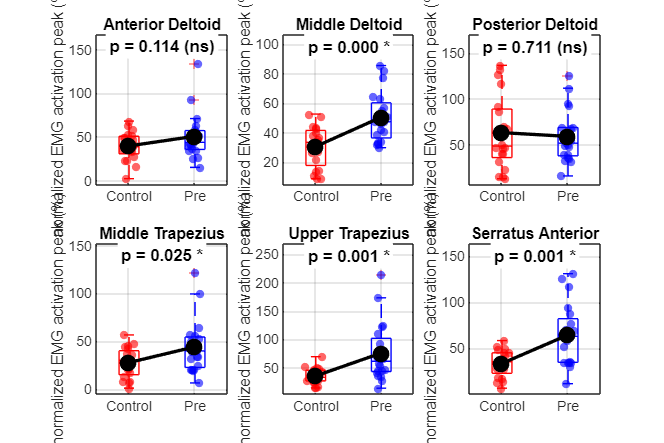


% 2. Asymptomatique vs Pre (indépendant)
perform_statistical_analysis(data_asympt_combined, data_pre_combined, 'Control', 'Pre', false, muscles);

=== Analyse statistique: Pre vs Post (apparié) ===

--- Anterior Deltoid ---
Test utilisé: Test t apparié (normalité: p = 0.1360)
Pre: M = 50.82, ET = 26.14; Post: M = 51.07, ET = 21.53
Résultat: t(19) = -0.03, p = 0.9743 (non significatif)
Interprétation: Pas de différence significative entre Pre et Post
Taille d'effet: d de Cohen = 0.01 (effet négligeable)

--- Middle Deltoid ---


Test utilisé: Test t apparié (normalité: p = 0.5000)
Pre: M = 50.52, ET = 16.88; Post: M = 42.43, ET = 10.25
Résultat: t(19) = 1.96, p = 0.0642 (non significatif)
Interprétation: Pas de différence significative entre Pre et Post
Taille d'effet: d de Cohen = -0.44 (effet faible)

--- Posterior Deltoid ---
Test utilisé: Test t apparié (normalité: p = 0.1169)
Pre: M = 58.93, ET = 28.63; Post: M = 72.48, ET = 25.89
Résultat: t(19) = -1.72, p = 0.1011 (non significatif)
Interprétation: Pas de différence significative entre Pre et Post
Taille d'effet: d de Cohen = 0.39 (effet faible)

--- Middle Trapezius ---
Test utilisé: Test de Wilcoxon (échantillons appariés) (normalité: p = 0.0380)
Pre: M = 44.23, ET = 27.53; Post: M = 29.90, ET = 17.13
Résultat: Z = 1.87, p = 0.0620 (non significatif)
Interprétation: Pas de différence significative entre Pre et Post
Taille d'effet: d de Cohen = -0.46 (effet faible)

--- Upper Trapezius ---


Test utilisé: Test de Wilcoxon (échantillons appariés) (normalité: p = 0.0010)
Pre: M = 76.11, ET = 50.97; Post: M = 46.96, ET = 11.65
Résultat: Z = 2.05, p = 0.0400 (significatif)
Interprétation: diminution significative entre Pre et Post
Taille d'effet: d de Cohen = -0.53 (effet moyen)

--- Serratus Anterior ---


Test utilisé: Test t apparié (normalité: p = 0.5000)
Pre: M = 64.45, ET = 33.39; Post: M = 52.12, ET = 21.17
Résultat: t(19) = 1.59, p = 0.1281 (non significatif)
Interprétation: Pas de différence significative entre Pre et Post
Taille d'effet: d de Cohen = -0.36 (effet faible)



=== Tableau récapitulatif: Pre vs Post ===
           Muscle            Group1_Mean    Group1_SD    Group2_Mean    Group2_SD    Delta_Mean    Delta_SD    P_Value     Effect_Size
    _____________________    ___________    _________    ___________    _________    __________    ________    ________    ___________

    {'Anterior Deltoid' }      50.822        26.139        51.071        21.533       0.24852       34.015      0.97427     0.0073063 
    {'Middle Deltoid'   }      50.516        16.884        42.426        10.249       -8.0908       18.415     0.064228      -0.43935 
    {'Posterior Deltoid'}      58.925        28.628        72.484        25.894        13.558       35.186    

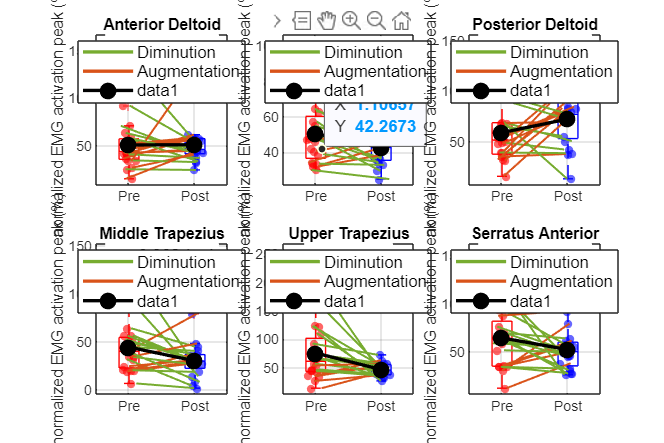


% 3. Pre vs Post (apparié)
perform_statistical_analysis(data_pre_combined(idx_pre,:), data_post_combined(idx_post,:), 'Pre', 'Post', true, muscles);